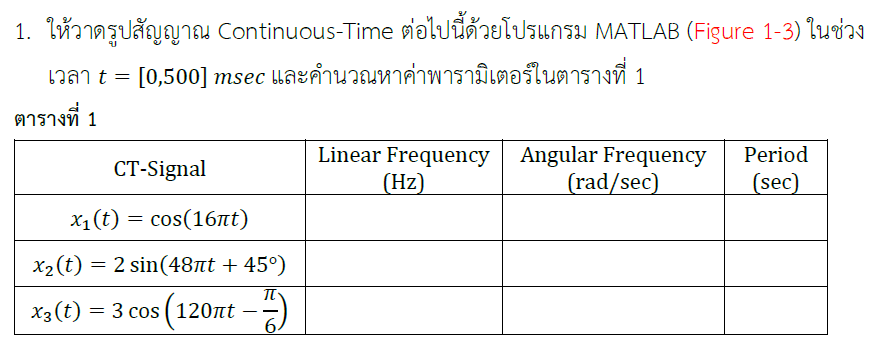

clear 
	
linearFreq_x1_t = 16*pi/(2*pi)

linearFreq_x1_t = 8

AngularFreq_x1_t = 16*pi

AngularFreq_x1_t = 50.2655

Period_x1_t = 1./linearFreq_x1_t

Period_x1_t = 0.1250


linearFreq_x2_t = 48*pi/(2*pi)

linearFreq_x2_t = 24

AngularFreq_x2_t = 48*pi

AngularFreq_x2_t = 150.7964

Period_x2_t = 1./linearFreq_x2_t

Period_x2_t = 0.0417


linearFreq_x3_t = 120*pi/(2*pi)

linearFreq_x3_t = 60.0000

AngularFreq_x3_t = 120*pi

AngularFreq_x3_t = 376.9911

Period_x3_t = 1./linearFreq_x3_t

Period_x3_t = 0.0167


t = linspace(0,0.5,5000);

x1 = cos(16*pi*t);
x2 = 2*sin(48*pi*t + pi/4);
x3 = 3*cos(120*pi*t - pi/6);

**Plot Graph**

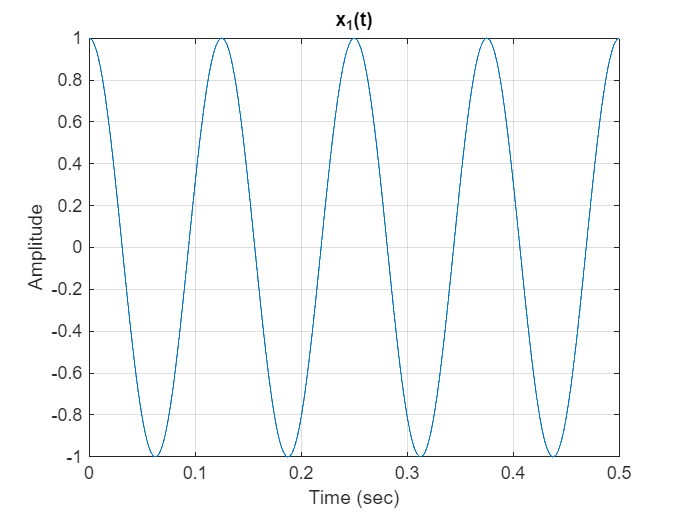

figure(1)
plot(t,x1)
xlabel('Time (sec)')
ylabel('Amplitude')
title('x_1(t)')
grid on

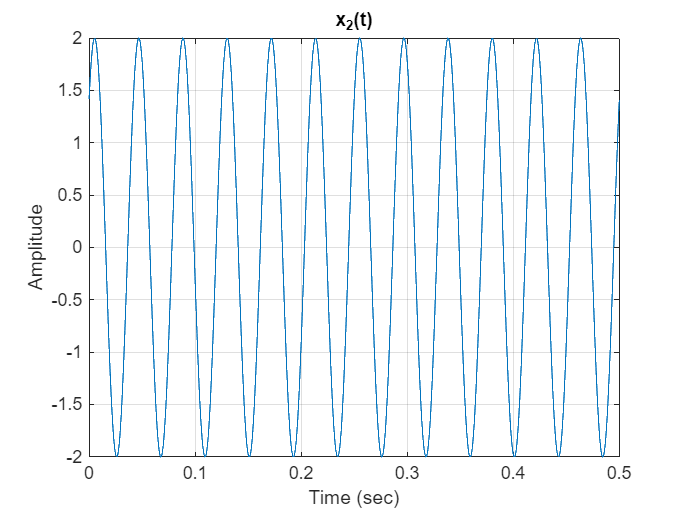

savefig('Figure1.fig')

figure(2)
plot(t,x2)
xlabel('Time (sec)')
ylabel('Amplitude')
title('x_2(t)')
grid on

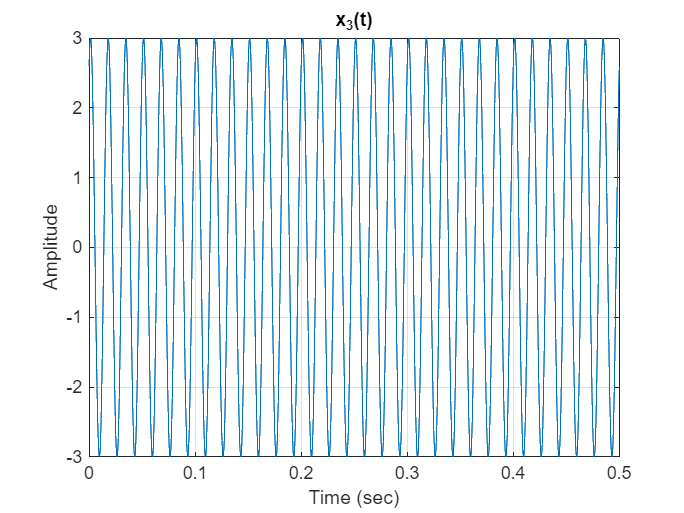

savefig('Figure2.fig')

figure(3)
plot(t,x3)
xlabel('Time (sec)')
ylabel('Amplitude')
title('x_3(t)')
grid on

savefig('Figure3.fig')

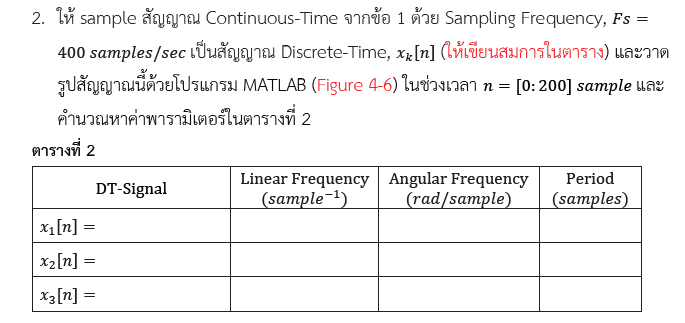

clear

FS = 400;
n = 0:200;

AngularFreq_x1_n = 16*pi/FS

AngularFreq_x1_n = 0.1257

AngularFreq_x2_n = 48*pi/FS

AngularFreq_x2_n = 0.3770

AngularFreq_x3_n = 120*pi/FS

AngularFreq_x3_n = 0.9425


linearFreq_x1_n = AngularFreq_x1_n/(2*pi)

linearFreq_x1_n = 0.0200

linearFreq_x2_n = AngularFreq_x2_n/(2*pi)

linearFreq_x2_n = 0.0600

linearFreq_x3_n = AngularFreq_x3_n/(2*pi)

linearFreq_x3_n = 0.1500


Period_x1_n		= 1./linearFreq_x1_n

Period_x1_n = 50

Period_x2_n     = 1./linearFreq_x2_n

Period_x2_n = 16.6667

Period_x3_n     = 1./linearFreq_x3_n

Period_x3_n = 6.6667


x1_n            = cos(AngularFreq_x1_n*n);
x2_n            = 2*sin((AngularFreq_x2_n*n)+ pi/4);
x3_n            = 3*cos((AngularFreq_x3_n*n)+ pi/6);

**Plot Graph**

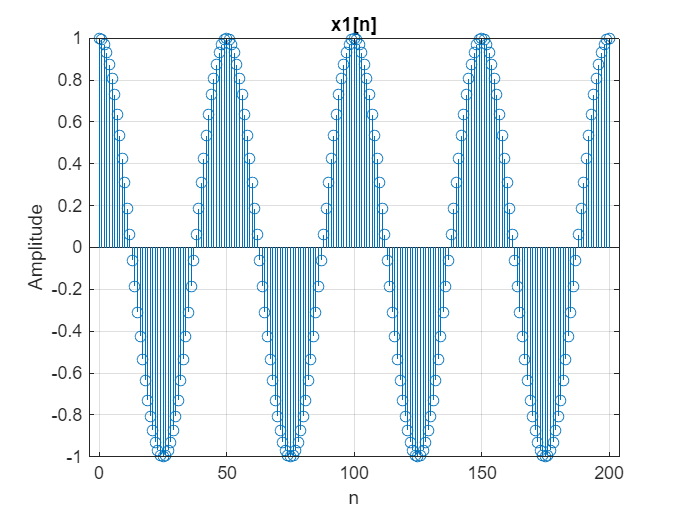

figure(4)
stem(n,x1_n)
xlabel('n')
ylabel('Amplitude')
title('x1[n]')
grid on

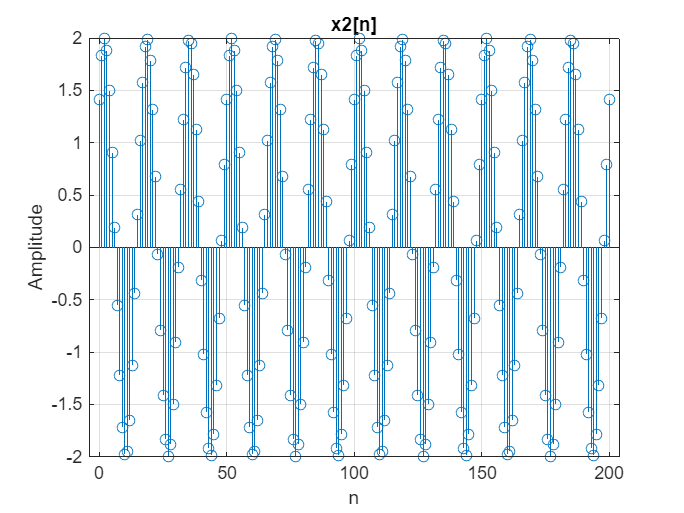

savefig('Figure4.fig')

figure(5)
stem(n,x2_n)
xlabel('n')
ylabel('Amplitude')
title('x2[n]')
grid on

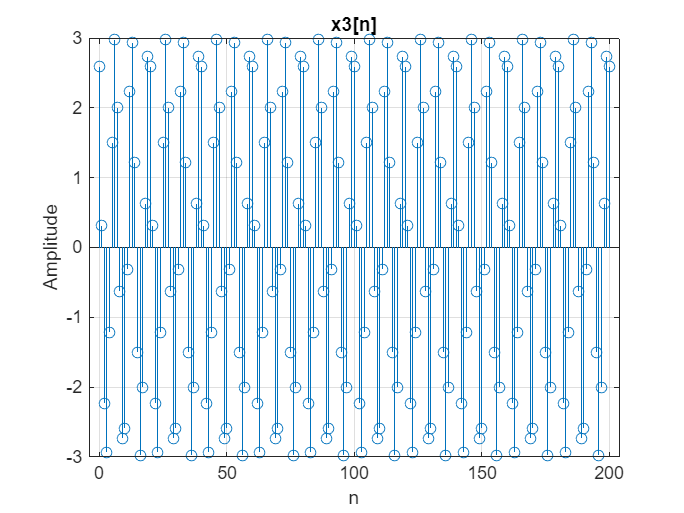

savefig('Figure5.fig')

figure(6)
stem(n,x3_n)
xlabel('n')
ylabel('Amplitude')
title('x3[n]')
grid on

savefig('Figure6.fig')

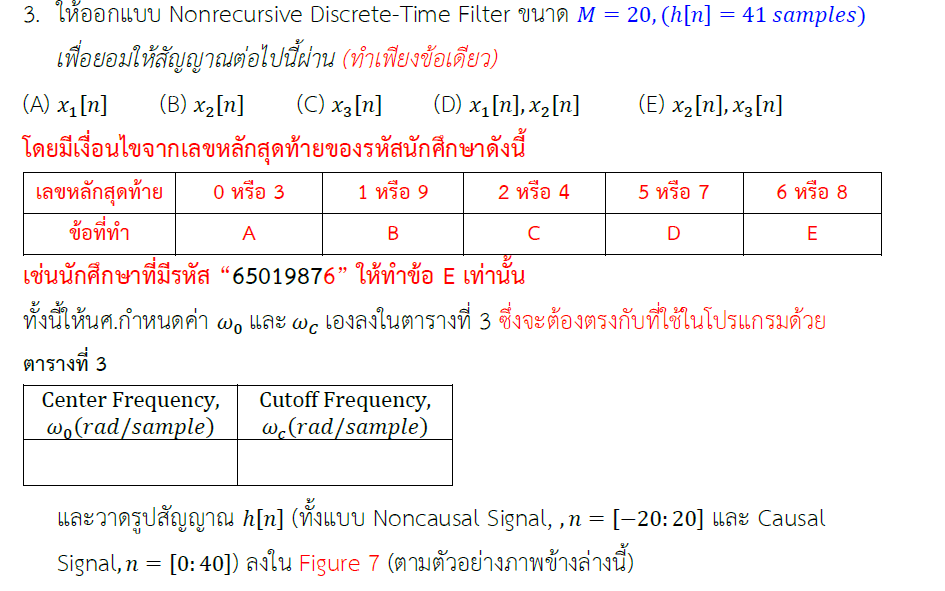

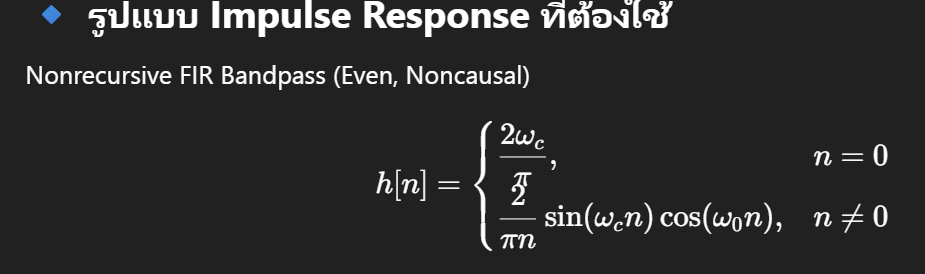

clear
M = 20;
n = -M:M;
w0 = 0.3*pi     % center frequency w x3

w0 = 0.9425

wc = 0.05*pi    % cutoff frequency

wc = 0.1571

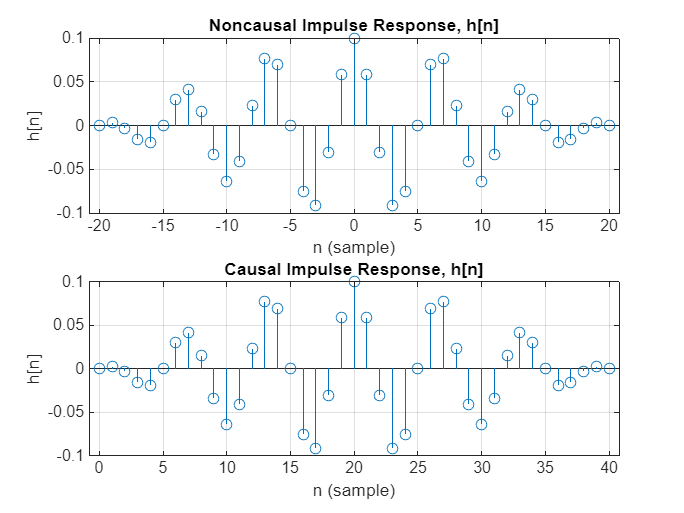


h = zeros(size(n));

for k = 1: length(n)
	if n(k) == 0
		h(k) = 2*wc/pi;
	else
		h(k) = (2/(pi*n(k))) * sin(wc*n(k)) *cos(w0*n(k));
	end
end
figure(7)
% ---- Noncausal Impulse Response ----
subplot(2,1,1)
stem(n,h)
xlabel('n (sample)')
ylabel('h[n]')
title('Noncausal Impulse Response, h[n]')
grid on
% ---- Causal Impulse Response ----
hc = h;   % shift to causal
nc = 0:2*M;
subplot(2,1,2)
stem(nc,hc)
xlabel('n (sample)')
ylabel('h[n]')
title('Causal Impulse Response, h[n]')
grid on

savefig('hn = DesignFIR(wo,wc,M)');


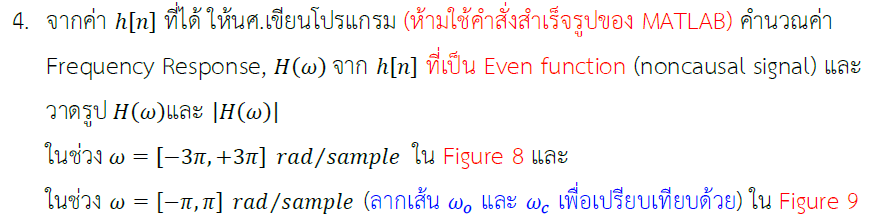

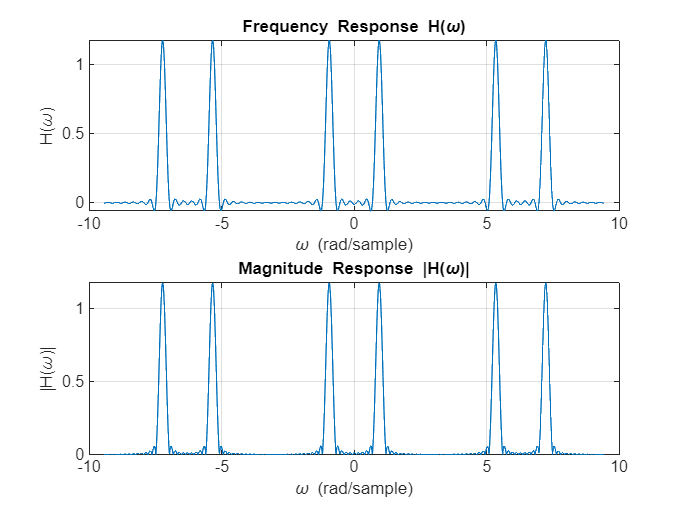

clear
clear
M = 20;
n = -M:M;

w0 = 0.3*pi;
wc = 0.05*pi;

h = zeros(size(n));

for k = 1:length(n)
    if n(k) == 0
        h(k) = 2*wc/pi;
    else
        h(k) = (2/(pi*n(k))) * sin(wc*n(k)) * cos(w0*n(k));
    end
end

w = linspace(-3*pi, 3*pi, 2000);
H = zeros(size(w));

for k = 1:length(w)
    H(k) = h(M+1);   % h[0]
    for n1 = 1:M
        H(k) = H(k) + 2*h(M+1+n1)*cos(w(k)*n1);
    end
end
figure(8)

subplot(2,1,1)
plot(w, real(H))
xlabel('\omega (rad/sample)')
ylabel('H(\omega)')
title('Frequency Response H(\omega)')
grid on

subplot(2,1,2)
plot(w, abs(H))
xlabel('\omega (rad/sample)')
ylabel('|H(\omega)|')
title('Magnitude Response |H(\omega)|')
grid on

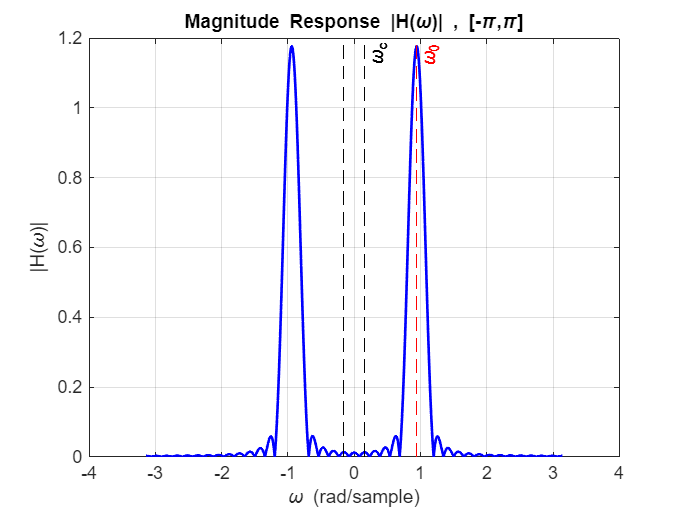


w2 = linspace(-pi, pi, 2000);
H2 = zeros(size(w2));

for k = 1:length(w2)
    H2(k) = h(M+1);
    for n1 = 1:M
        H2(k) = H2(k) + 2*h(M+1+n1)*cos(w2(k)*n1);
    end
end

figure(9)
plot(w2, abs(H2),'b','LineWidth',1.5)
hold on
xline(w0,'r--','\omega_0')
xline(wc,'k--','\omega_c')
xline(-wc,'k--')
xlabel('\omega (rad/sample)')
ylabel('|H(\omega)|')
title('Magnitude Response |H(\omega)| , [-\pi,\pi]')
grid on

savefig('[Hw,w] = DisplayHw(hn)');

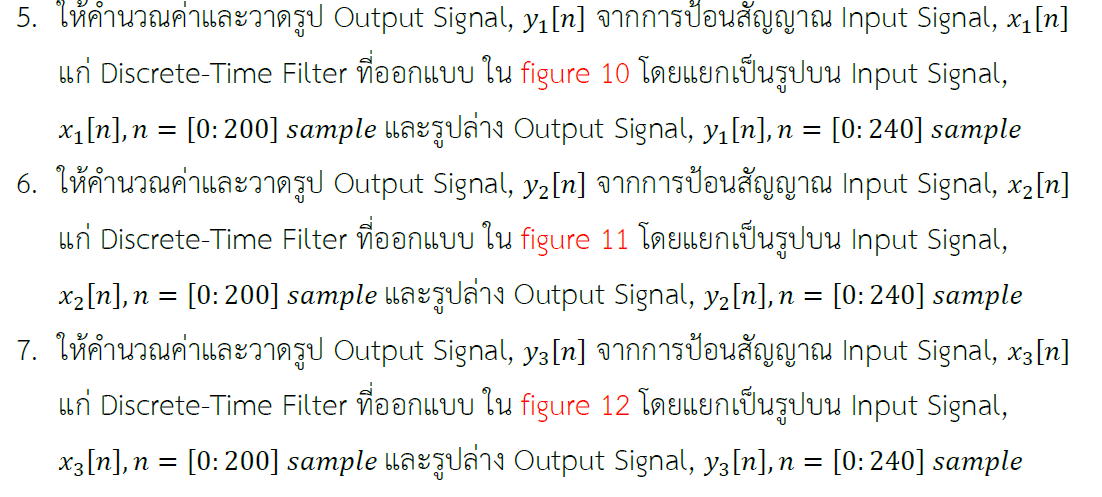

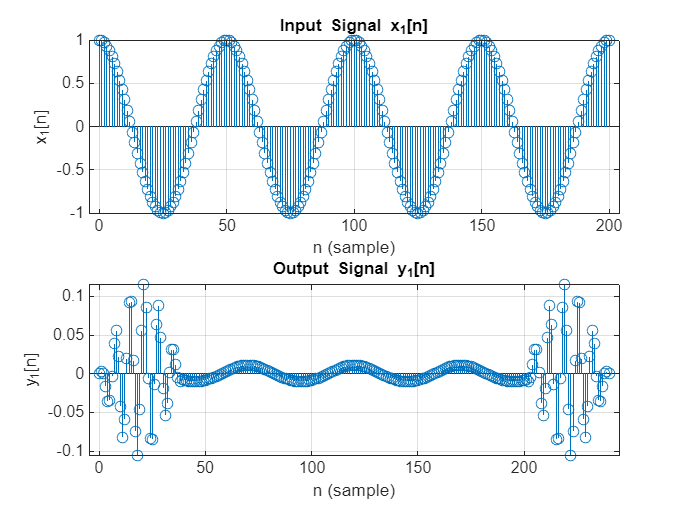

M = 20;
hc = h;        % h[n], n = 0:40
n1 = 0:200;
FS = 400;

x1 = cos(16*pi*n1/FS);
x2 = 2*sin(48*pi*n1/FS + pi/4);
x3 = 3*cos(120*pi*n1/FS - pi/6);

y1 = zeros(1, length(n1) + length(hc) - 1);
ny = 0:length(y1)-1;

for n = 1:length(y1)
    for k = 1:length(hc)
        if (n-k+1 > 0) && (n-k+1 <= length(x1))
            y1(n) = y1(n) + hc(k)*x1(n-k+1);
        end
    end
end
figure(10)

subplot(2,1,1)
stem(n1,x1)
xlabel('n (sample)')
ylabel('x_1[n]')
title('Input Signal x_1[n]')
grid on

subplot(2,1,2)
stem(ny,y1)
xlabel('n (sample)')
ylabel('y_1[n]')
title('Output Signal y_1[n]')
grid on

6

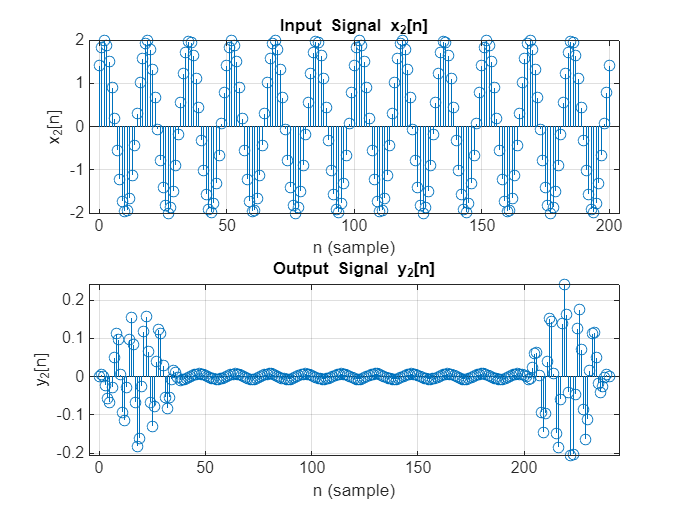

y2 = zeros(1, length(n1) + length(hc) - 1);

for n = 1:length(y2)
    for k = 1:length(hc)
        if (n-k+1 > 0) && (n-k+1 <= length(x2))
            y2(n) = y2(n) + hc(k)*x2(n-k+1);
        end
    end
end

figure(11)

subplot(2,1,1)
stem(n1,x2)
xlabel('n (sample)')
ylabel('x_2[n]')
title('Input Signal x_2[n]')
grid on

subplot(2,1,2)
stem(ny,y2)
xlabel('n (sample)')
ylabel('y_2[n]')
title('Output Signal y_2[n]')
grid on

7

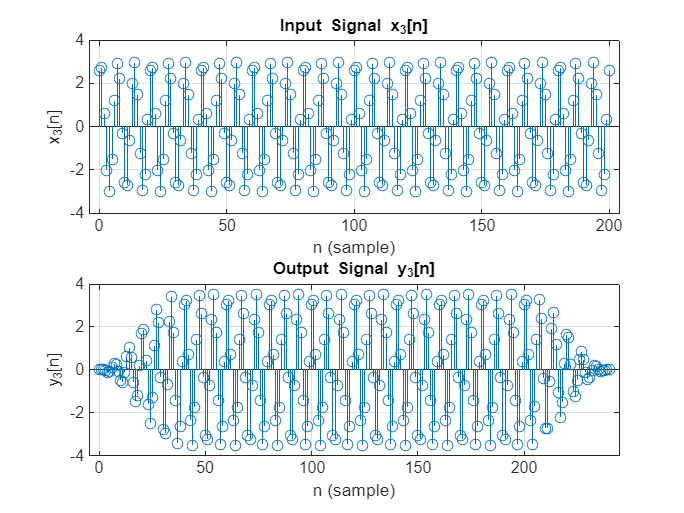

y3 = zeros(1, length(n1) + length(hc) - 1);

for n = 1:length(y3)
    for k = 1:length(hc)
        if (n-k+1 > 0) && (n-k+1 <= length(x3))
            y3(n) = y3(n) + hc(k)*x3(n-k+1);
        end
    end
end
figure(12)

subplot(2,1,1)
stem(n1,x3)
xlabel('n (sample)')
ylabel('x_3[n]')
title('Input Signal x_3[n]')
grid on

subplot(2,1,2)
stem(ny,y3)
xlabel('n (sample)')
ylabel('y_3[n]')
title('Output Signal y_3[n]')
grid on